addpath(genpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\FineAlignment\GliraICP"));
ICPoutlier=load("C:\Users\agori\Documents\MATLAB\MSc\Validation\2blocksROS2\AfterOutlierRemoved\ICP.mat");
ICPraw=load("C:\Users\agori\Documents\MATLAB\MSc\Validation\2blocksROS2\AfterNew\ICP.mat");

ICPoutlier_stats=ICPoutlier.obj.D.stats;
ICPraw_stats=ICPraw.obj.D.stats;

arrMean_outlier=zeros(1, 5); 
arrMean_raw=zeros(1, 5); 
arrStd_outlier=zeros(1, 5); 
arrStd_raw=zeros(1, 5); 
arrNobs_outlier=zeros(1, 5); 
arrNobs_raw=zeros(1, 5); 
arrNorms_outlier=zeros(1, 5); 
arrNorms_raw=zeros(1, 5); 
%ICPoutlier_stats{1,1}.mean_vWithoutGrossErrors;
for k=1:5
    arrMean_outlier(k)=ICPoutlier_stats{1,k}.mean_vWithoutGrossErrors;
    arrMean_raw(k)=ICPraw_stats{1,k}.mean_vWithoutGrossErrors;
    
    arrStd_outlier(k)= ICPoutlier_stats{1,k}.std_vWithoutGrossErrors;
    arrStd_raw(k)=ICPraw_stats{1,k}.std_vWithoutGrossErrors;

    arrNobs_outlier(k)=ICPoutlier_stats{1,k}.nObs;
    arrNobs_raw(k)=ICPraw_stats{1,k}.nObs; 

    arrNorms_outlier(k)= ICPoutlier_stats{1,k}.normdx;
    arrNorms_raw(k)=ICPraw_stats{1,k}.normdx;
end

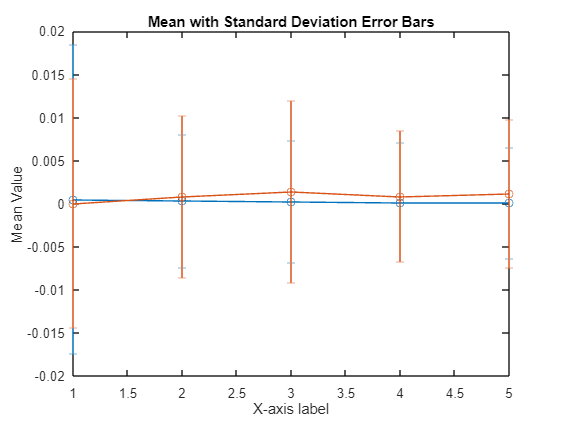

nums=1:5;
errorbar(nums, arrMean_raw, arrStd_raw, 'o-');
hold on
errorbar(nums, arrMean_outlier, arrStd_outlier, 'o-');
hold off
xlabel('X-axis label');
ylabel('Mean Value');
title('Mean with Standard Deviation Error Bars');

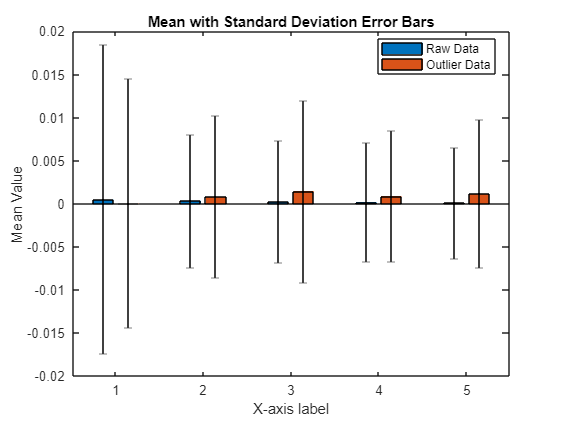

nums = 1:5; % X-axis categories


% Combine means into a matrix (each row corresponds to a category)
means = [arrMean_raw; arrMean_outlier]';

% Create grouped bar plot
figure;
b = bar(nums, means, 'grouped');
hold on;

% Calculate bar centers for error bars
numGroups = size(means, 1); % Number of x-axis points
numBars = size(means, 2);   % Number of bars per group
groupWidth = min(0.8, numBars / (numBars + 1.5)); % Width of bar groups

for i = 1:numBars
    xOffsets = b(i).XEndPoints; % X positions for each bar
    if i == 1
        errorbar(xOffsets, arrMean_raw, arrStd_raw, 'k', 'linestyle', 'none');
    else
        errorbar(xOffsets, arrMean_outlier, arrStd_outlier, 'k', 'linestyle', 'none');
    end
end

hold off;
xlabel('X-axis label');
ylabel('Mean Value');
title('Mean with Standard Deviation Error Bars');
legend({'Raw Data', 'Outlier Data'}, 'Location', 'Best');

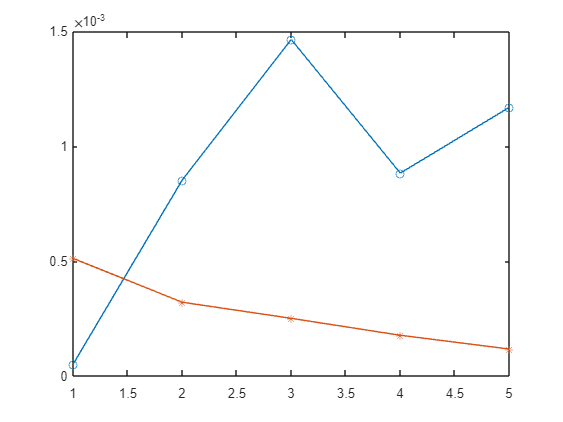

plot(nums,arrMean_outlier,'o-');
hold on
plot(nums,arrMean_raw,'*-');
hold off

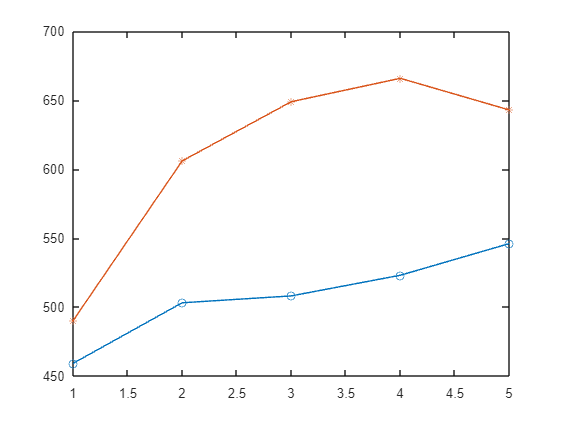

plot(nums,arrNobs_outlier,'o-');
hold on
plot(nums,arrNobs_raw,'*-');
hold off

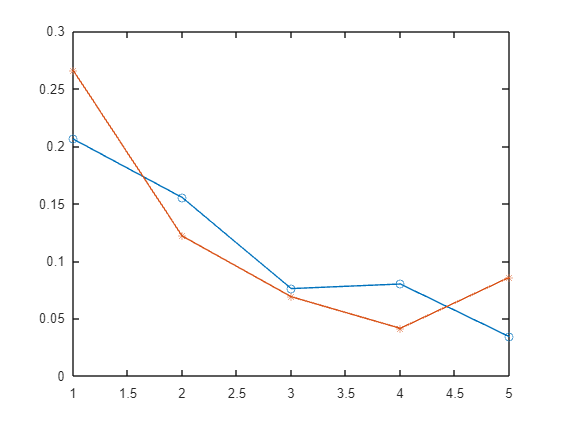

plot(nums,arrNorms_outlier,'o-');
hold on
plot(nums,arrNorms_raw,'*-');
hold off

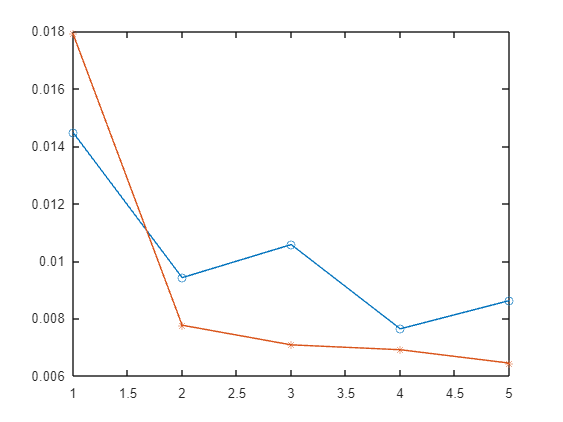

plot(nums,arrStd_outlier,'o-');
hold on
plot(nums,arrStd_raw,'*-');
hold off